**Checking whether two sample t-test in S and Bai works for normal vectors:**

Generate $N = 3000$ i.i.d. gaussian ensembles $X_i$ in $\mathbb{R}^{40\times 40}$; each $X_i$ has i.i.d. N(0,1) elements. We apply S and Bai to test whether there is a change in $\mathbb{E}(X_i)$ at several locations: 400, 800, 1200, 1600, 2000, 2400. Under the null, the p-value should be uniform.

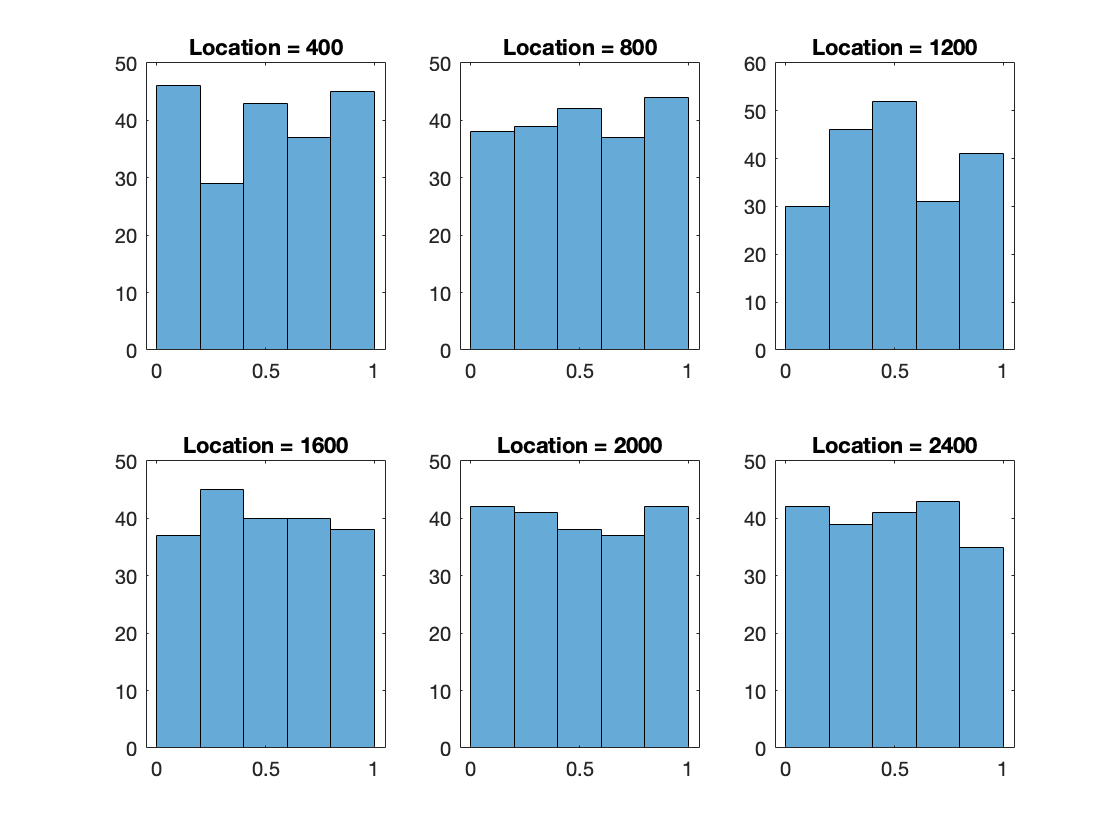

%% Bai
clear;clc;
record = zeros(100,1);
figure;
for loc = 1:6
    for tt = 1:200
        X  =  normrnd(0, 1, [40, 40, 3000]);
        y  =  ones(3000, 1);
        screen_opts = struct(...
            'nr', 40,...
            'nc', 40,...
            'N' , 3e3 ,...
            'inc', 10,...
            'method', 'B',...
            'comb_flag', 'cauchy');

        startInd = 400 * loc;
        endInd   = 400 * loc;

        [p_value, outInfo_result] = preScreen_M(y, X, startInd, endInd, screen_opts);

        %plot(outInfo_result.test_pos, outInfo_result.p_value_original);
        record(tt) = p_value;

        subplot(2,3,loc);
        histogram(record);
        title(['Location = ', num2str(loc*400)]);
    end
end

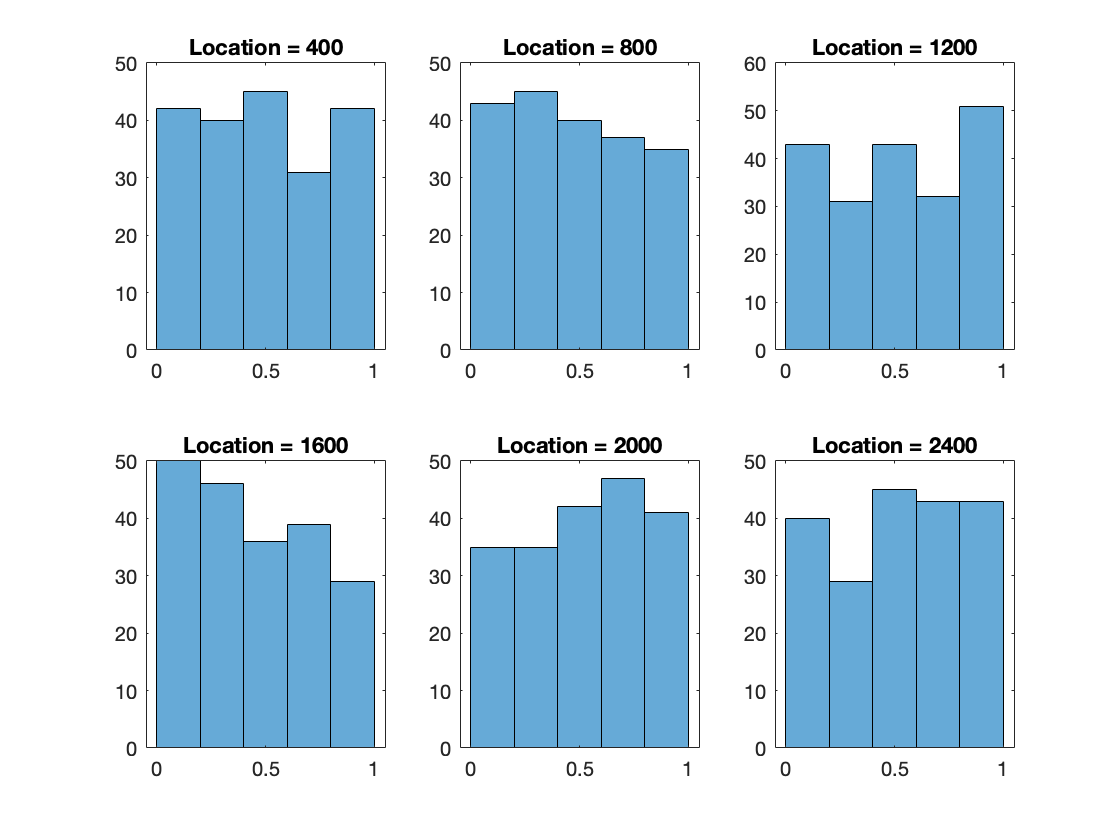


%% S
clear;clc;
record = zeros(100,1);
figure;
for loc = 1:6
    for tt = 1:200
        X  =  normrnd(0, 1, [40, 40, 3000]);
        y  =  ones(3000, 1);
        screen_opts = struct(...
            'nr', 40,...
            'nc', 40,...
            'N' , 3e3 ,...
            'inc', 10,...
            'method', 'B',...
            'comb_flag', 'cauchy');

        startInd = 400 * loc;
        endInd   = 400 * loc;

        [p_value, outInfo_result] = preScreen_M(y, X, startInd, endInd, screen_opts);

        %plot(outInfo_result.test_pos, outInfo_result.p_value_original);
        record(tt) = p_value;

        subplot(2,3,loc);
        histogram(record);
        title(['Location = ', num2str(loc*400)]);
    end
end

**Checking whether the two sample t-test in S and Bai works for the score in low rank matrix case (zero change point).**

The model is $y = \text{Tr}(X^\top\Theta) + \epsilon.$

For the design matrix, we generate 3000 i.i.d. $X_i$ from $X$ in $\mathbb{R}^{40\times 40}$ with i.i.d. gaussian entries. The true signal $\Theta$ is constructed as follows:


$$\Theta = U V^\top,$$


where $U, V$ in $\mathbb{R}^{40\times 5}$ are the first five left and right singular vectors of a Gaussian ensemble in $\mathbb{R}^{100\times 100}$. The noise $\epsilon$ are i.i.d. from $N(0,0.5^2)$.

The score is given by $Z_i = y_i X_i$. This corresponds to the gradient of the quadratic loss at $\Theta = 0$. That is, $\nabla L(\Theta)\mid_{\Theta = 0} = \sum y_iX_i$.

We only test the position 1500; we should expect a uniform p-value. 

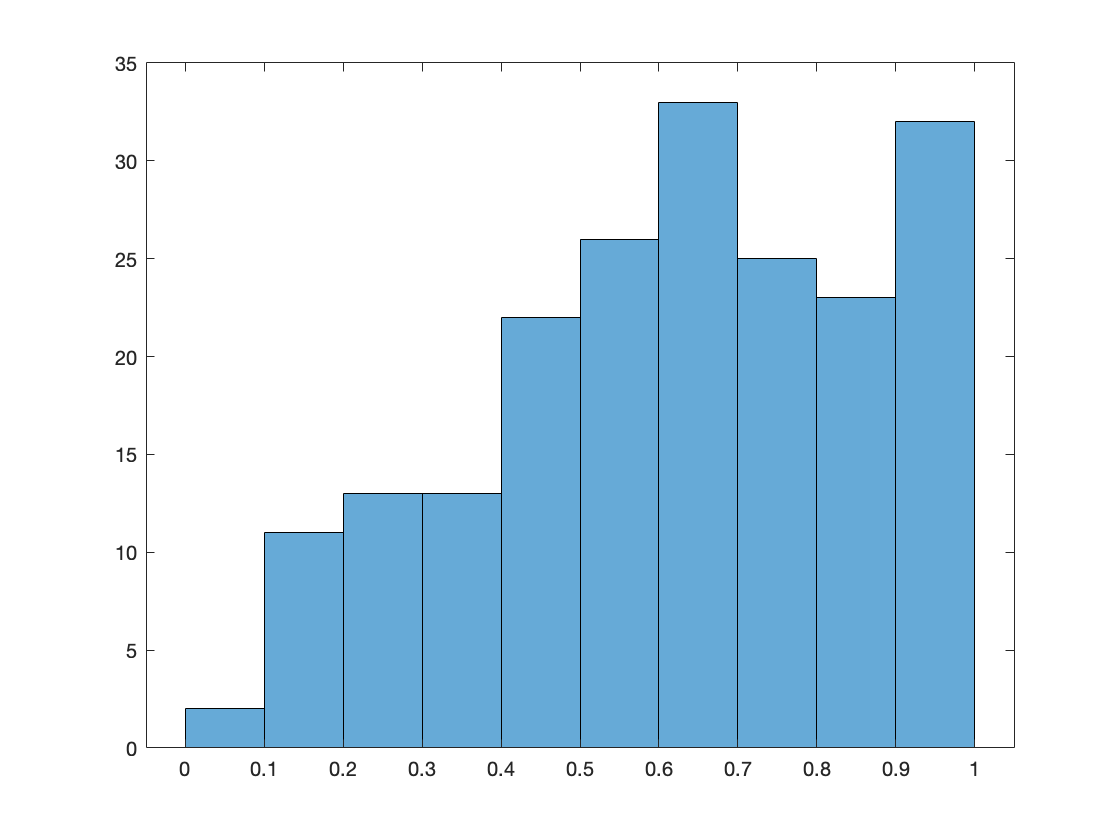

%% Zero change point: Bai
clear;clc;
N       =   3000;
nr      =   40;
nc      =   40;
r       =   5;
s       =   1;
Theta_star = zeros(nr, nc, s);

for k = 1:s
    [U,~,~]     =   svd(normrnd(0,1,[nr, 100]), 'econ');
    [V,~,~]     =   svd(normrnd(0,1,[nc, 100]), 'econ');
    Theta_star(:,:,k)  =  U(:, 1:r) * V(:, 1:r)' / sqrt(r);
end

noise     = struct(...
    'type',  'Gaussian',...
    'scale', 1.0,...
    'para',  0.5);
design    = struct(...
    'type',  'CS',...
    'dist',  'Gaussian',...
    'scale', 1.0,...
    'para',  1.0);

data_opts = struct(...
    'nr', nr,...
    'nc', nc,...
    'N' , N,...
    'r' , r,...
    's' , s,...
    'noise',  noise,...
    'design', design, ...
    'mech', 'given', ...
    'Theta_star', Theta_star);

screen_opts = struct(...
    'nr', nr,...
    'nc', nc,...
    'N' , N ,...
    'inc', 1,...
    'method', 'B',...
    'comb_flag', 'cauchy');

startInd = 1500;
endInd   = 1500;

for tt = 1:200
    [y, X, outInfo_data]  =  DataGen_ChangePoints(data_opts);
    [p_value, outInfo_result] = preScreen_M(y, X, startInd, endInd, screen_opts);
    record(tt) = p_value;
end

figure;
histogram(record);

disp(num2str(mean(record)));

0.61752


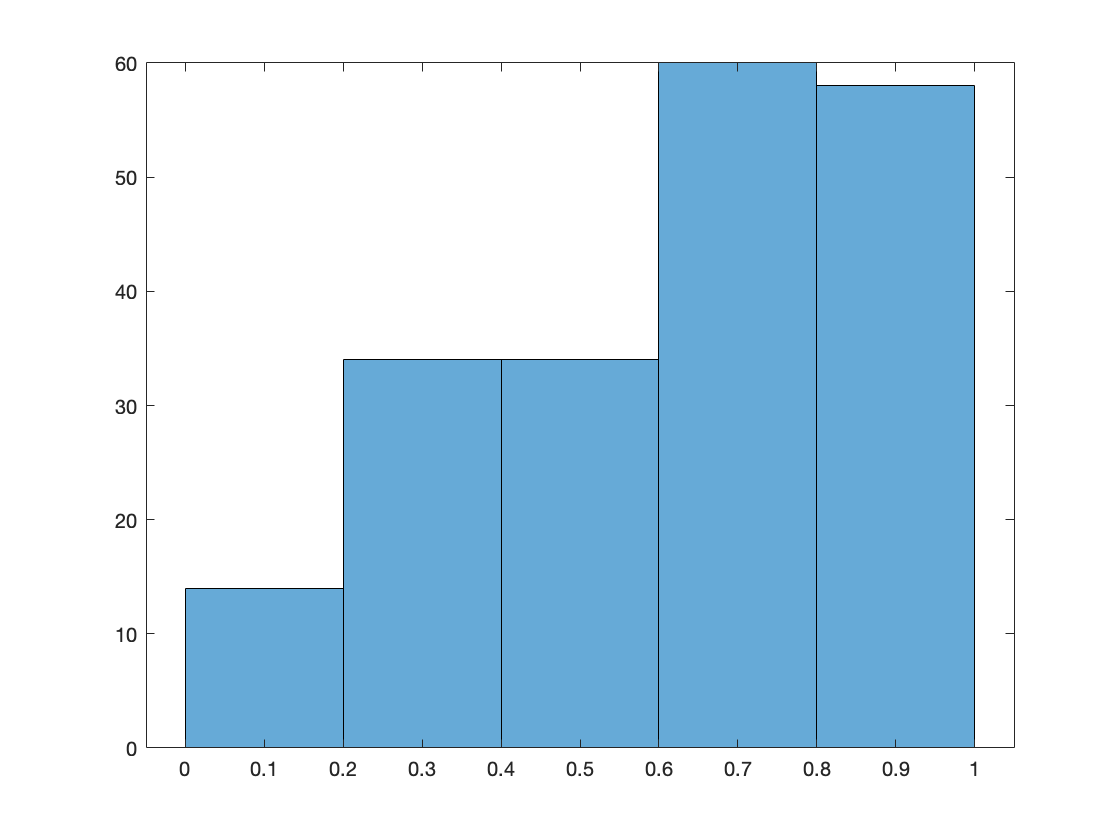

%% Zero change point: S
clear;clc;
N       =   3000;
nr      =   40;
nc      =   40;
r       =   5;
s       =   1;
Theta_star = zeros(nr, nc, s);

for k = 1:s
    [U,~,~]     =   svd(normrnd(0,1,[nr, 100]), 'econ');
    [V,~,~]     =   svd(normrnd(0,1,[nc, 100]), 'econ');
    Theta_star(:,:,k)  =  U(:, 1:r) * V(:, 1:r)' / sqrt(r);
end

noise     = struct(...
    'type',  'Gaussian',...
    'scale', 1.0,...
    'para',  0.5);
design    = struct(...
    'type',  'CS',...
    'dist',  'Gaussian',...
    'scale', 1.0,...
    'para',  1.0);

data_opts = struct(...
    'nr', nr,...
    'nc', nc,...
    'N' , N,...
    'r' , r,...
    's' , s,...
    'noise',  noise,...
    'design', design, ...
    'mech', 'given', ...
    'Theta_star', Theta_star);

screen_opts = struct(...
    'nr', nr,...
    'nc', nc,...
    'N' , N ,...
    'inc', 1,...
    'method', 'S',...
    'comb_flag', 'cauchy');

startInd = 1500;
endInd   = 1500;

for tt = 1:200
    [y, X, outInfo_data]  =  DataGen_ChangePoints(data_opts);
    [p_value, outInfo_result] = preScreen_M(y, X, startInd, endInd, screen_opts);
    record(tt) = p_value;
end

figure;
histogram(record);

disp(num2str(mean(record)));

0.61955


**Check whether this works when there is a single break.**

The setting is very similar to the previous one. But now we have on change point at location 1600. Before 1600 and after 1600 the data follows the trace regression model. We run two sample t at many positions (loc = 400:20:2600 in MATLAB coding style). Then we do a Cauchy combination and report the combined p-value. 

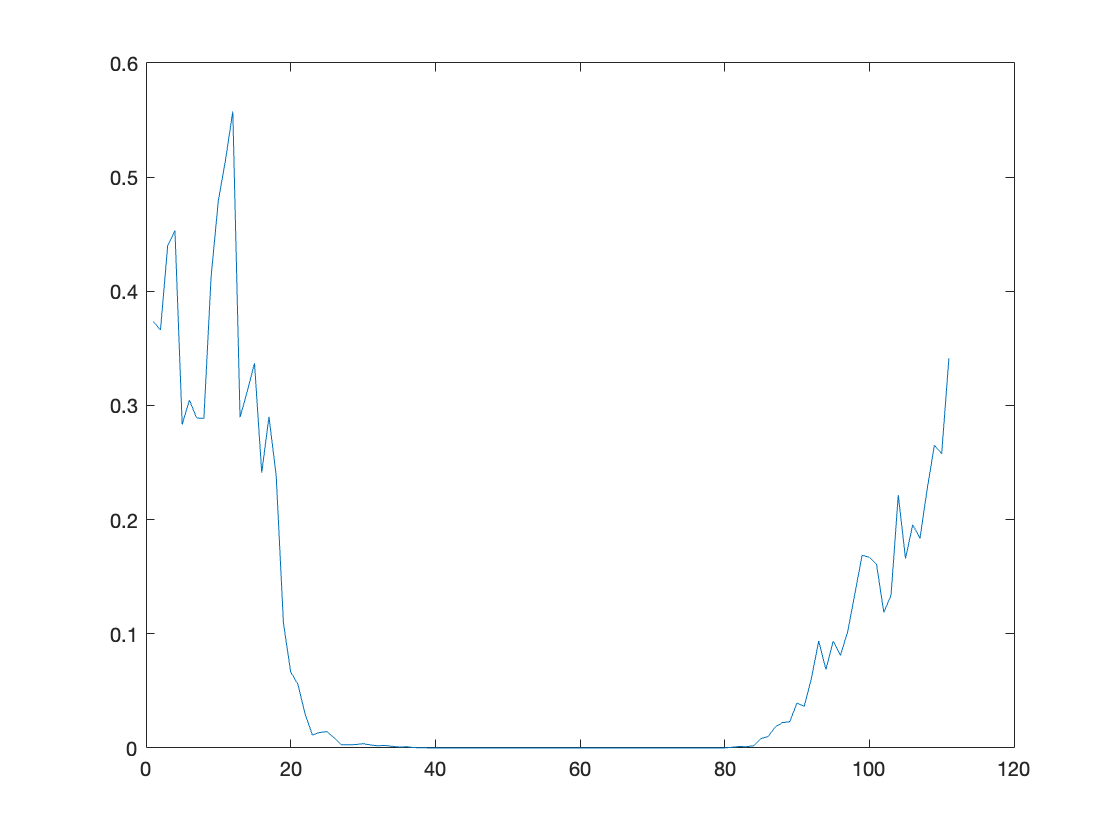

clear;clc;
N       =   [1600, 1400];
nr      =   40;
nc      =   40;
r       =   5;
s       =   2;

noise     = struct(...
    'type',  'Gaussian',...
    'scale', 1.0,...
    'para',  0.5);
design    = struct(...
    'type',  'CS',...
    'dist',  'Gaussian',...
    'scale', 1.0,...
    'para',  1.0);

data_opts = struct(...
    'nr', nr,...
    'nc', nc,...
    'N' , N,...
    'r' , r,...
    's' , s,...
    'noise',  noise,...
    'design', design);


screen_opts = struct(...
    'nr', nr,...
    'nc', nc,...
    'N' , N ,...
    'inc', 20,...
    'method', 'B',...
    'comb_flag', 'cauchy');

startInd = 400;
endInd   = 2600;

[p_value, ~, ~, outInfo] = runTrial(startInd, endInd, data_opts, screen_opts);

figure;
plot(outInfo.result.p_value_original);

disp(num2str(p_value));

3.4392e-12
